clearvars;
load("BackupData.mat")

%Creates tables to display the results
%The table is done this way to allow for
%quicker table modifications.
disp('|');disp('|');disp('|');

|
|
|


disp('Triangle Arm = Model 1')

Triangle Arm = Model 1


Show1 = table();
Show1.Material = names;
Show1.Mass_of_Arm_kg=DroneArm1;
Show1.Max_Payload_kg = PayloadMax1;
Show1.Acceptable = Useable1;
Show1.Max_Disp = Max_Disp1;
Show1.Max_Stress = Max_Stress1;
Show1.Factor_of_Safety = FoS1;
Show1.Cost = cost1;
Show1.Total_Cost = cost1*4;
Show1.Cost_mass_total = cost1g*4;
disp(Show1)

               Material                Mass_of_Arm_kg    Max_Payload_kg    Acceptable     Max_Disp     Max_Stress    Factor_of_Safety      Cost       Total_Cost    Cost_mass_total
    _______________________________    ______________    ______________    __________    __________    __________    ________________    _________    __________    _______________

    "Carbon Fiber Composite (CFRP)"        0.05344          0.78624          "Yes"       0.00086339    2.3943e+07          25.06           0.90179       3.6072          13.892    
    "Aluminum Alloy"                      0.090179          0.63928          "Yes"       0.00086131    2.3564e+07      


disp('|');disp('|');disp('|');

|
|
|


disp('Drone_arm_sm = Model 2')

Drone_arm_sm = Model 2


Show2 = table();
Show2.Material = names;
Show2.Mass_of_Arm_kg=DroneArm2;
Show2.Max_Payload_kg = PayloadMax2;
Show2.Acceptable = Useable2;
Show2.Max_Disp = Max_Disp2;
Show2.Max_Stress = Max_Stress2;
Show2.Factor_of_Safety = FoS2;
Show2.Cost = cost2;
Show2.Total_Cost = cost2*4;
Show2.Cost_mass_total = cost2g*4;
disp(Show2)

               Material                Mass_of_Arm_kg    Max_Payload_kg    Acceptable     Max_Disp     Max_Stress    Factor_of_Safety       Cost       Total_Cost    Cost_mass_total
    _______________________________    ______________    ______________    __________    __________    __________    ________________    __________    __________    _______________

    "Carbon Fiber Composite (CFRP)"       0.024813          0.90075          "Yes"       0.00021511    1.5817e+07         37.934            0.60804        2.4322         4.3238    
    "Aluminum Alloy"                      0.041873          0.83251          "Yes"       0.00021558    1.5094e+07   


disp('|');disp('|');disp('|');

|
|
|


disp('Beam Arm = Model 3')

Beam Arm = Model 3


Show3 = table();
Show3.Material = names;
Show3.Mass_of_Arm_kg=DroneArm3;
Show3.Max_Payload_kg = PayloadMax3;
Show3.Acceptable = Useable3;
Show3.Max_Disp = Max_Disp3;
Show3.Max_Stress = Max_Stress3;
Show3.Factor_of_Safety = FoS3;
Show3.Cost = cost3;
Show3.Total_Cost = cost3*4;
Show3.Cost_mass_total = cost3g*4;
disp(Show3)

               Material                Mass_of_Arm_kg    Max_Payload_kg    Acceptable     Max_Disp     Max_Stress    Factor_of_Safety      Cost      Total_Cost    Cost_mass_total
    _______________________________    ______________    ______________    __________    __________    __________    ________________    ________    __________    _______________

    "Carbon Fiber Composite (CFRP)"       0.038095          0.84762          "Yes"       0.00086339    2.3943e+07          25.06            0.648        2.592          4.608     
    "Aluminum Alloy"                      0.064285          0.74286          "Yes"       0.00086131    2.3564e+07         


disp('|');disp('|');disp('|');

|
|
|


disp('Lattice Arm = Model 4')

Lattice Arm = Model 4


Show4 = table();
Show4.Material = names;
Show4.Mass_of_Arm_kg=DroneArm4;
Show4.Max_Payload_kg = PayloadMax4;
Show4.Acceptable = Useable4;
Show4.Max_Disp = Max_Disp4;
Show4.Max_Stress = Max_Stress4;
Show4.Factor_of_Safety = FoS4;
Show4.Cost = cost4;
Show4.Total_Cost = cost4*4;
Show4.Cost_mass_total = cost4g*4;
disp(Show4)

               Material                Mass_of_Arm_kg    Max_Payload_kg    Acceptable     Max_Disp     Max_Stress    Factor_of_Safety      Cost       Total_Cost    Cost_mass_total
    _______________________________    ______________    ______________    __________    __________    __________    ________________    _________    __________    _______________

    "Carbon Fiber Composite (CFRP)"       0.091297          0.63481          "Yes"       7.3542e-05    9.9942e+06         60.035            3.7137       14.855          26.409    
    "Aluminum Alloy"                       0.15406          0.38375          "No"        7.2613e-05    9.7572e+06      


%Max_Displacement = max(Result.Displacement.Magnitude)
%Max_Stress = max(Result.VonMisesStress)
%FoS = materials(1).yieldStrength_Pa/Max_Stress

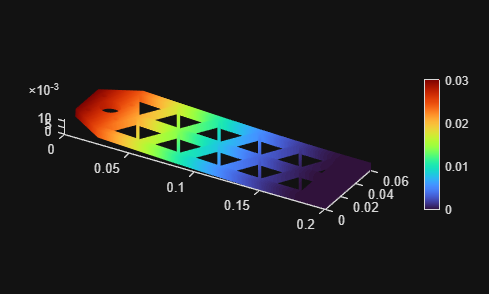

% Data to visualize
meshData = Model_1_result_ASB.Mesh;
nodalData = Model_1_result_ASB.Displacement.Magnitude;
deformationData = Model_1_result_ASB.Displacement;

% Create PDE result visualization
resultViz2 = pdeviz(meshData,abs(real(nodalData)), ...
    "DeformationData",deformationData, ...
    "DeformationScaleFactor",0.19688, ...
    "ColorLimits",[0 0.03048]);


% Clear temporary variables
clearvars meshData nodalData deformationData